# Análisis de la información de las métricas de difusividad en sujetos con riesgo genético para enfermedad de Alzheimer

En este anáisis preliminar se obtendrán los estadísticos necesarios para realizar una prueba de hipótesis paramétrica con respecto a la diferencia de medias poblacionales con varianzas desconocidas y diferentes para las distintas métricas entre los grupos de estudio.

## Importación de los datos a partir del archivo de Excel que contiene los datos armonizados.

A = readtable('DATOS_FINALES_ARMONIZADOS.xlsx')

A = 204×11 table
        DM          FA          AD            RD          Sujeto          SITE          Grupo       Sexo    Edad    Escolaridad    MMSE
    __________    _______    _________    __________    ___________    __________    ___________    ____    ____    ___________    ____

    0.00095383    0.31751    0.0012651    0.00079861    {'DCL4380'}    {'SITE_B'}    {'DCL'    }     1        72        17          30 
    0.00098323     0.3547    0.0013039    0.00082311    {'AD6595' }    {'SITE_B'}    {'AD_ADNI'}     1        80        14          18 
     0.0009699    0.32018    0.0012736    0.00081844    {'AD4964

### Generación de las matrices de información de acuerdo a las categorías de los sujetos de estudio.

Matriz de datos para el grupo con enfermedad de Alzheimer.

ad_adni = [A.DM(categorical(A.Grupo) == 'AD_ADNI') ...
    A.FA(categorical(A.Grupo) == 'AD_ADNI') ...
    A.AD(categorical(A.Grupo) == 'AD_ADNI') ...
    A.RD(categorical(A.Grupo) == 'AD_ADNI') ...
    A.MMSE(categorical(A.Grupo) == 'AD_ADNI') ...
    A.Edad(categorical(A.Grupo) == 'AD_ADNI')...
    A.Sexo(categorical(A.Grupo) == 'AD_ADNI')];

Matriz de datos para el grupo control de los sujetos con enfermedad de Alzheimer.

cnad_adni = [A.DM(categorical(A.Grupo) == 'CNAD_ADNI') ...
    A.FA(categorical(A.Grupo) == 'CNAD_ADNI') ...
    A.AD(categorical(A.Grupo) == 'CNAD_ADNI') ...
    A.RD(categorical(A.Grupo) == 'CNAD_ADNI') ...
    A.MMSE(categorical(A.Grupo) == 'CNAD_ADNI') ...
    A.Edad(categorical(A.Grupo) == 'CNAD_ADNI')...
    A.Sexo(categorical(A.Grupo) == 'CNAD_ADNI')];

Matriz de datos para el grupo de sujetos con deterioro cognitivo leve.

dcl = [A.DM(categorical(A.Grupo) == 'DCL') ...
    A.FA(categorical(A.Grupo) == 'DCL') ...
    A.AD(categorical(A.Grupo) == 'DCL') ...
    A.RD(categorical(A.Grupo) == 'DCL') ...
    A.MMSE(categorical(A.Grupo) == 'DCL') ...
    A.Edad(categorical(A.Grupo) == 'DCL')...
    A.Sexo(categorical(A.Grupo) == 'DCL')];

Matriz de datos para el grupo control de los sujetos con deterioro cognitivo leve.

 cndcl = [A.DM(categorical(A.Grupo) == 'CNDCL')...
    A.FA(categorical(A.Grupo) == 'CNDCL')...
    A.AD(categorical(A.Grupo) == 'CNDCL')...
    A.RD(categorical(A.Grupo) == 'CNDCL')...
    A.MMSE(categorical(A.Grupo) == 'CNDCL')...
    A.Edad(categorical(A.Grupo) == 'CNDCL')...
    A.Sexo(categorical(A.Grupo) == 'CNDCL')];

Matriz de datos para el grupo de sujetos sanos portadores del gen.

 portadores = [A.DM(categorical(A.Grupo) == 'PORTADORES')...
    A.FA(categorical(A.Grupo) == 'PORTADORES')...
    A.AD(categorical(A.Grupo) == 'PORTADORES')...
    A.RD(categorical(A.Grupo) == 'PORTADORES')...
    A.MMSE(categorical(A.Grupo) == 'PORTADORES')...
    A.Edad(categorical(A.Grupo) == 'PORTADORES')...
    A.Sexo(categorical(A.Grupo) == 'PORTADORES')];

Matriz de datos para el grupo de sujetos sanos que no son portadores del gen.

 no_portadores = [A.DM((categorical(A.Grupo) == 'NO_PORTADORES') & A.Edad <= 48) ...
    A.FA((categorical(A.Grupo) == 'NO_PORTADORES') & A.Edad <= 48) ...
    A.AD((categorical(A.Grupo) == 'NO_PORTADORES') & A.Edad <= 48) ...
    A.RD((categorical(A.Grupo) == 'NO_PORTADORES') & A.Edad <= 48) ...
    A.MMSE((categorical(A.Grupo) == 'NO_PORTADORES') & A.Edad <= 48) ...
    A.Edad((categorical(A.Grupo) == 'NO_PORTADORES') & A.Edad <= 48)...
    A.Sexo((categorical(A.Grupo) == 'NO_PORTADORES') & A.Edad <= 48)];


Índices de los vectores de datos:

- [:,1] = Difusividad media

- [:,2] = Anisotropía fraccional

- [:,3] = Difusividad axial

- [:,4] = Difusividad radial

- [:,5] = Score del MMSE

- [:,6] = Edad del sujeto

### Generación de los histogramas para las variables analizadas

#### Análisis de la anisotropía fraccional

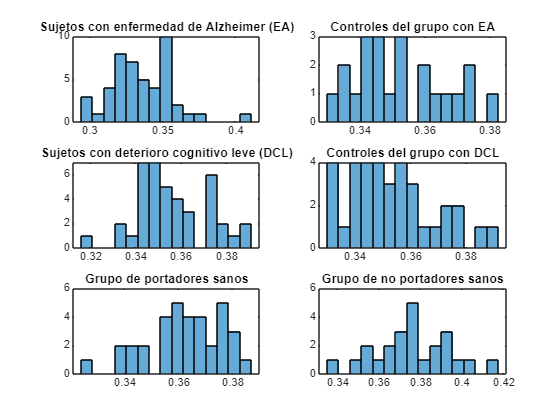

figure(1)
subplot(3,2,1) 
histogram(ad_adni(:,2),15)
title('Sujetos con enfermedad de Alzheimer (EA)')
subplot(3,2,2)
histogram(cnad_adni(:,2),15)
title('Controles del grupo con EA')
subplot(3,2,3)
histogram(dcl(:,2),15)
title('Sujetos con deterioro cognitivo leve (DCL)')
subplot(3,2,4)
histogram(cndcl(:,2),15)
title('Controles del grupo con DCL')
subplot(3,2,5)
histogram(portadores(:,2),15)
title('Grupo de portadores sanos')
subplot(3,2,6)
histogram(no_portadores(:,2),15)
title('Grupo de no portadores sanos')

#### Análisis de la difusividad media

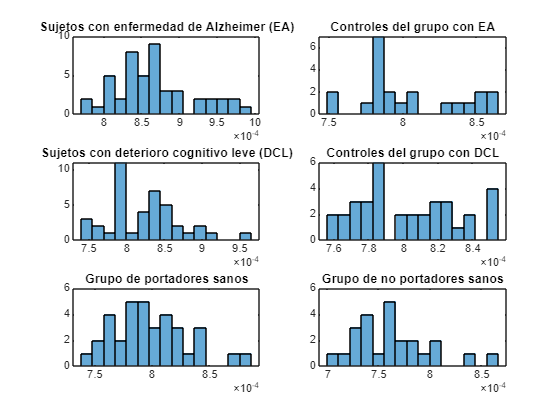

figure(2)
subplot(3,2,1) 
histogram(ad_adni(:,1),15)
title('Sujetos con enfermedad de Alzheimer (EA)')
subplot(3,2,2)
histogram(cnad_adni(:,1),15)
title('Controles del grupo con EA')
subplot(3,2,3)
histogram(dcl(:,1),15)
title('Sujetos con deterioro cognitivo leve (DCL)')
subplot(3,2,4)
histogram(cndcl(:,1),15)
title('Controles del grupo con DCL')
subplot(3,2,5)
histogram(portadores(:,1),15)
title('Grupo de portadores sanos')
subplot(3,2,6)
histogram(no_portadores(:,1),15)
title('Grupo de no portadores sanos')

#### Análisis de la difusividad axial

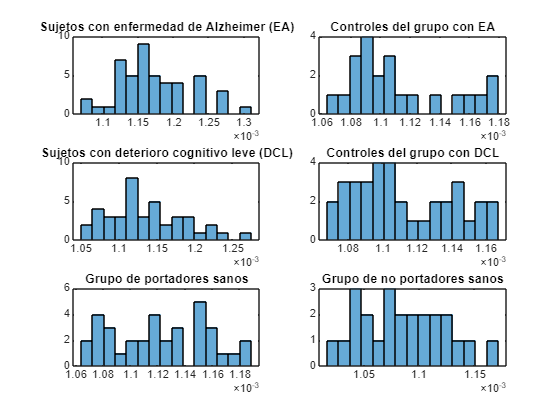

figure(3)
subplot(3,2,1) 
histogram(ad_adni(:,3),15)
title('Sujetos con enfermedad de Alzheimer (EA)')
subplot(3,2,2)
histogram(cnad_adni(:,3),15)
title('Controles del grupo con EA')
subplot(3,2,3)
histogram(dcl(:,3),15)
title('Sujetos con deterioro cognitivo leve (DCL)')
subplot(3,2,4)
histogram(cndcl(:,3),15)
title('Controles del grupo con DCL')
subplot(3,2,5)
histogram(portadores(:,3),15)
title('Grupo de portadores sanos')
subplot(3,2,6)
histogram(no_portadores(:,3),15)
title('Grupo de no portadores sanos')

#### Análisis de la difusividad radial

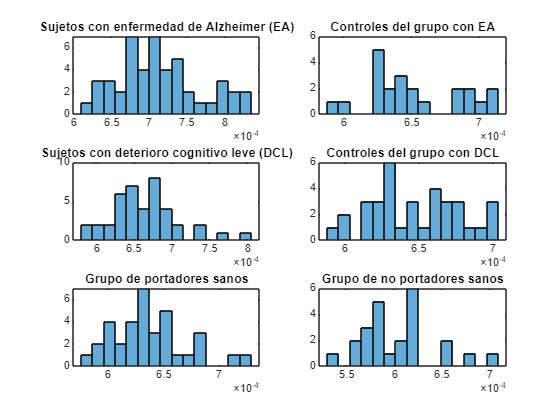

figure(4)
subplot(3,2,1) 
histogram(ad_adni(:,4),15)
title('Sujetos con enfermedad de Alzheimer (EA)')
subplot(3,2,2)
histogram(cnad_adni(:,4),15)
title('Controles del grupo con EA')
subplot(3,2,3)
histogram(dcl(:,4),15)
title('Sujetos con deterioro cognitivo leve (DCL)')
subplot(3,2,4)
histogram(cndcl(:,4),15)
title('Controles del grupo con DCL')
subplot(3,2,5)
histogram(portadores(:,4),15)
title('Grupo de portadores sanos')
subplot(3,2,6)
histogram(no_portadores(:,4),15)
title('Grupo de no portadores sanos')

#### Análisis de la puntuación de la prueba MMSE

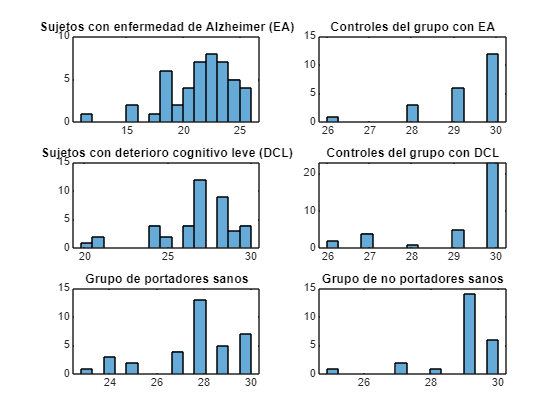

figure(5)
subplot(3,2,1) 
histogram(ad_adni(:,5),15)
title('Sujetos con enfermedad de Alzheimer (EA)')
subplot(3,2,2)
histogram(cnad_adni(:,5),15)
title('Controles del grupo con EA')
subplot(3,2,3)
histogram(dcl(:,5),15)
title('Sujetos con deterioro cognitivo leve (DCL)')
subplot(3,2,4)
histogram(cndcl(:,5),15)
title('Controles del grupo con DCL')
subplot(3,2,5)
histogram(portadores(:,5),15)
title('Grupo de portadores sanos')
subplot(3,2,6)
histogram(no_portadores(:,5),15)
title('Grupo de no portadores sanos')

## Pruebas de bondad de ajuste para determinar la normalidad en la distribución de las métricas para cada grupo analizado

### Grupo de sujetos con enfermedad de Alzheimer

T_DM(1,1) = kstest((ad_adni(:,1) - mean(ad_adni(:,1)))/std(ad_adni(:,1))); 
T_AF(1,1) = kstest((ad_adni(:,2) - mean(ad_adni(:,2)))/std(ad_adni(:,2))); 
T_AD(1,1) = kstest((ad_adni(:,3) - mean(ad_adni(:,3)))/std(ad_adni(:,3))); 
T_RD(1,1) = kstest((ad_adni(:,4) - mean(ad_adni(:,4)))/std(ad_adni(:,4)));

if T_DM(1,1) == 0   
    fprintf("La prueba Kolmogorov-Smirnov valida que la distribución de los datos muestrales para la difusividad media \n en el grupo de sujetos con enfermedad de Alzheimer es aproximadamente normal")
else
    fprintf("La prueba Kolmogorov-Smirnov rechaza que la distribución de los datos muestrales para la difusividad media \n en el grupo de sujetos con enfermedad de Alzheimer es aproximadamente normal")
end

La prueba Kolmogorov-Smirnov valida que la distribución de los datos muestrales para la difusividad media 
 en el grupo de sujetos con enfermedad de Alzheimer es aproximadamente normal

if T_AF(1,1) == 0
    fprintf("La prueba Kolmogorov-Smirnov valida que la distribución de los datos muestrales para la anisotroía fraccional \n en el grupo de sujetos con enfermedad de Alzheimer es aproximadamente normal")
else
    fprintf("La prueba Kolmogorov-Smirnov rechaza que la distribución de los datos muestrales para la anisotroía fraccional \n en el grupo de sujetos con enfermedad de Alzheimer es aproximadamente normal")
end

La prueba Kolmogorov-Smirnov valida que la distribución de los datos muestrales para la anisotroía fraccional 
 en el grupo de sujetos con enfermedad de Alzheimer es aproximadamente normal

if T_AD(1,1) == 0
    fprintf("La prueba Kolmogorov-Smirnov valida que la distribución de los datos muestrales para la difusividad axonal \n en el grupo de sujetos con enfermedad de Alzheimer es aproximadamente normal")
else
    fprintf("La prueba Kolmogorov-Smirnov rechaza que la distribución de los datos muestrales para la difusividad axonal \n en el grupo de sujetos con enfermedad de Alzheimer es aproximadamente normal")
end

La prueba Kolmogorov-Smirnov valida que la distribución de los datos muestrales para la difusividad axonal 
 en el grupo de sujetos con enfermedad de Alzheimer es aproximadamente normal

if T_RD(1,1) == 0
    fprintf("La prueba Kolmogorov-Smirnov valida que la distribución de los datos muestrales para la difusividad radial \n en el grupo de sujetos con enfermedad de Alzheimer es aproximadamente normal")
else
    fprintf("La prueba Kolmogorov-Smirnov rechaza que la distribución de los datos muestrales para la difusividad radial \n en el grupo de sujetos con enfermedad de Alzheimer es aproximadamente normal")
end

La prueba Kolmogorov-Smirnov valida que la distribución de los datos muestrales para la difusividad radial 
 en el grupo de sujetos con enfermedad de Alzheimer es aproximadamente normal

### Grupo de control para enfermedad de Alzheimer

T_DM(2,1) = kstest((cnad_adni(:,1) - mean(cnad_adni(:,1)))/std(cnad_adni(:,1))); 
T_AF(2,1) = kstest((cnad_adni(:,2) - mean(cnad_adni(:,2)))/std(cnad_adni(:,2))); 
T_AD(2,1) = kstest((cnad_adni(:,3) - mean(cnad_adni(:,3)))/std(cnad_adni(:,3))); 
T_RD(2,1) = kstest((cnad_adni(:,4) - mean(cnad_adni(:,4)))/std(cnad_adni(:,4)));

if T_DM(2,1) == 0
    fprintf("La prueba Kolmogorov-Smirnov valida que la distribución de los datos muestrales para la difusividad media \n en el grupo de control para enfermedad de Alzheimer es aproximadamente normal")
else
    fprintf("La prueba Kolmogorov-Smirnov rechaza que la distribución de los datos muestrales para la difusividad media \n en el grupo de control para enfermedad de Alzheimer es aproximadamente normal")
end

La prueba Kolmogorov-Smirnov valida que la distribución de los datos muestrales para la difusividad media 
 en el grupo de control para enfermedad de Alzheimer es aproximadamente normal

if T_AF(2,1) == 0
    fprintf("La prueba Kolmogorov-Smirnov valida que la distribución de los datos muestrales para la anisotroía fraccional \n en el grupo de control para enfermedad de Alzheimer es aproximadamente normal")
else
    fprintf("La prueba Kolmogorov-Smirnov rechaza que la distribución de los datos muestrales para la anisotroía fraccional \n en el grupo de control para enfermedad de Alzheimer es aproximadamente normal")
end

La prueba Kolmogorov-Smirnov valida que la distribución de los datos muestrales para la anisotroía fraccional 
 en el grupo de control para enfermedad de Alzheimer es aproximadamente normal

if T_AD(2,1) == 0
    fprintf("La prueba Kolmogorov-Smirnov valida que la distribución de los datos muestrales para la difusividad axonal \n en el grupo de control para enfermedad de Alzheimer es aproximadamente normal")
else
    fprintf("La prueba Kolmogorov-Smirnov rechaza que la distribución de los datos muestrales para la difusividad axonal \n en el grupo de control para enfermedad de Alzheimer es aproximadamente normal")
end

La prueba Kolmogorov-Smirnov valida que la distribución de los datos muestrales para la difusividad axonal 
 en el grupo de control para enfermedad de Alzheimer es aproximadamente normal

if T_RD(2,1) == 0
    fprintf("La prueba Kolmogorov-Smirnov valida que la distribución de los datos muestrales para la difusividad radial \n en el grupo de control para enfermedad de Alzheimer es aproximadamente normal")
else
    fprintf("La prueba Kolmogorov-Smirnov rechaza que la distribución de los datos muestrales para la difusividad radial \n en el grupo de control para enfermedad de Alzheimer es aproximadamente normal")
end

La prueba Kolmogorov-Smirnov valida que la distribución de los datos muestrales para la difusividad radial 
 en el grupo de control para enfermedad de Alzheimer es aproximadamente normal

### Grupo de sujetos con deterioro cognitivo leve

T_DM(3,1) = kstest((dcl(:,1) - mean(dcl(:,1)))/std(dcl(:,1))); 
T_AF(3,1) = kstest((dcl(:,2) - mean(dcl(:,2)))/std(dcl(:,2))); 
T_AD(3,1) = kstest((dcl(:,3) - mean(dcl(:,3)))/std(dcl(:,3))); 
T_RD(3,1) = kstest((dcl(:,4) - mean(dcl(:,4)))/std(dcl(:,4)));

if T_DM(3,1) == 0
    fprintf("La prueba Kolmogorov-Smirnov valida que la distribución de los datos muestrales para la difusividad media \n en el grupo de sujetos con deterioro cognitivo leve es aproximadamente normal")
else
    fprintf("La prueba Kolmogorov-Smirnov rechaza que la distribución de los datos muestrales para la difusividad media \n en el grupo de sujetos con deterioro cognitivo leve es aproximadamente normal")
end

La prueba Kolmogorov-Smirnov valida que la distribución de los datos muestrales para la difusividad media 
 en el grupo de sujetos con deterioro cognitivo leve es aproximadamente normal

if T_AF(3,1) == 0
    fprintf("La prueba Kolmogorov-Smirnov valida que la distribución de los datos muestrales para la anisotroía fraccional \n en el grupo de sujetos con deterioro cognitivo leve es aproximadamente normal")
else
    fprintf("La prueba Kolmogorov-Smirnov rechaza que la distribución de los datos muestrales para la anisotroía fraccional \n en el grupo de sujetos con deterioro cognitivo leve es aproximadamente normal")
end

La prueba Kolmogorov-Smirnov valida que la distribución de los datos muestrales para la anisotroía fraccional 
 en el grupo de sujetos con deterioro cognitivo leve es aproximadamente normal

if T_AD(3,1) == 0
    fprintf("La prueba Kolmogorov-Smirnov valida que la distribución de los datos muestrales para la difusividad axonal \n en el grupo de sujetos con deterioro cognitivo leve es aproximadamente normal")
else
    fprintf("La prueba Kolmogorov-Smirnov rechaza que la distribución de los datos muestrales para la difusividad axonal \n en el grupo de sujetos con deterioro cognitivo leve es aproximadamente normal")
end

La prueba Kolmogorov-Smirnov valida que la distribución de los datos muestrales para la difusividad axonal 
 en el grupo de sujetos con deterioro cognitivo leve es aproximadamente normal

if T_RD(3,1) == 0
    fprintf("La prueba Kolmogorov-Smirnov valida que la distribución de los datos muestrales para la difusividad radial \n en el grupo de sujetos con deterioro cognitivo leve es aproximadamente normal")
else
    fprintf("La prueba Kolmogorov-Smirnov rechaza que la distribución de los datos muestrales para la difusividad radial \n en el grupo de sujetos con deterioro cognitivo leve es aproximadamente normal")
end

La prueba Kolmogorov-Smirnov valida que la distribución de los datos muestrales para la difusividad radial 
 en el grupo de sujetos con deterioro cognitivo leve es aproximadamente normal

### Grupo de control para deterioro cognitivo leve

T_DM(4,1) = kstest((cndcl(:,1) - mean(cndcl(:,1)))/std(cndcl(:,1))); 
T_AF(4,1) = kstest((cndcl(:,2) - mean(cndcl(:,2)))/std(cndcl(:,2))); 
T_AD(4,1) = kstest((cndcl(:,3) - mean(cndcl(:,3)))/std(cndcl(:,3))); 
T_RD(4,1) = kstest((cndcl(:,4) - mean(cndcl(:,4)))/std(cndcl(:,4)));

if T_DM(4,1) == 0
    fprintf("La prueba Kolmogorov-Smirnov valida que la distribución de los datos muestrales para la difusividad media \n en el grupo de control para deterioro cognitivo leve es aproximadamente normal")
else
    fprintf("La prueba Kolmogorov-Smirnov rechaza que la distribución de los datos muestrales para la difusividad media \n en el grupo de control para deterioro cognitivo leve es aproximadamente normal")
end

La prueba Kolmogorov-Smirnov valida que la distribución de los datos muestrales para la difusividad media 
 en el grupo de control para deterioro cognitivo leve es aproximadamente normal

if T_AF(4,1) == 0
    fprintf("La prueba Kolmogorov-Smirnov valida que la distribución de los datos muestrales para la anisotroía fraccional \n en el grupo de control para deterioro cognitivo leve es aproximadamente normal")
else
    fprintf("La prueba Kolmogorov-Smirnov rechaza que la distribución de los datos muestrales para la anisotroía fraccional \n en el grupo de control para deterioro cognitivo leve es aproximadamente normal")
end

La prueba Kolmogorov-Smirnov valida que la distribución de los datos muestrales para la anisotroía fraccional 
 en el grupo de control para deterioro cognitivo leve es aproximadamente normal

if T_AD(4,1) == 0
    fprintf("La prueba Kolmogorov-Smirnov valida que la distribución de los datos muestrales para la difusividad axonal \n en el grupo de control para deterioro cognitivo leve es aproximadamente normal")
else
    fprintf("La prueba Kolmogorov-Smirnov rechaza que la distribución de los datos muestrales para la difusividad axonal \n en el grupo de control para deterioro cognitivo leve es aproximadamente normal")
end

La prueba Kolmogorov-Smirnov valida que la distribución de los datos muestrales para la difusividad axonal 
 en el grupo de control para deterioro cognitivo leve es aproximadamente normal

if T_RD(4,1) == 0
    fprintf("La prueba Kolmogorov-Smirnov valida que la distribución de los datos muestrales para la difusividad radial \n en el grupo de control para deterioro cognitivo leve es aproximadamente normal")
else
    fprintf("La prueba Kolmogorov-Smirnov rechaza que la distribución de los datos muestrales para la difusividad radial \n en el grupo de control para deterioro cognitivo leve es aproximadamente normal")
end

La prueba Kolmogorov-Smirnov valida que la distribución de los datos muestrales para la difusividad radial 
 en el grupo de control para deterioro cognitivo leve es aproximadamente normal

### Grupo de sujetos sanos portadores

T_DM(5,1) = kstest((portadores(:,1) - mean(portadores(:,1)))/std(portadores(:,1))); 
T_AF(5,1) = kstest((portadores(:,2) - mean(portadores(:,2)))/std(portadores(:,2))); 
T_AD(5,1) = kstest((portadores(:,3) - mean(portadores(:,3)))/std(portadores(:,3))); 
T_RD(5,1) = kstest((portadores(:,4) - mean(portadores(:,4)))/std(portadores(:,4)));

if T_DM(5,1) == 0
    fprintf("La prueba Kolmogorov-Smirnov valida que la distribución de los datos muestrales para la difusividad media \n en el grupo de sujetos sanos portadores es aproximadamente normal")
else
    fprintf("La prueba Kolmogorov-Smirnov rechaza que la distribución de los datos muestrales para la difusividad media \n en el grupo de sujetos sanos portadores es aproximadamente normal")
end

La prueba Kolmogorov-Smirnov valida que la distribución de los datos muestrales para la difusividad media 
 en el grupo de sujetos sanos portadores es aproximadamente normal

if T_AF(5,1) == 0
    fprintf("La prueba Kolmogorov-Smirnov valida que la distribución de los datos muestrales para la anisotroía fraccional \n en el grupo de sujetos sanos portadores es aproximadamente normal")
else
    fprintf("La prueba Kolmogorov-Smirnov rechaza que la distribución de los datos muestrales para la anisotroía fraccional \n en el grupo de sujetos sanos portadores es aproximadamente normal")
end

La prueba Kolmogorov-Smirnov valida que la distribución de los datos muestrales para la anisotroía fraccional 
 en el grupo de sujetos sanos portadores es aproximadamente normal

if T_AD(5,1) == 0
    fprintf("La prueba Kolmogorov-Smirnov valida que la distribución de los datos muestrales para la difusividad axonal \n en el grupo de sujetos sanos portadores es aproximadamente normal")
else
    fprintf("La prueba Kolmogorov-Smirnov rechaza que la distribución de los datos muestrales para la difusividad axonal \n en el grupo de sujetos sanos portadores es aproximadamente normal")
end

La prueba Kolmogorov-Smirnov valida que la distribución de los datos muestrales para la difusividad axonal 
 en el grupo de sujetos sanos portadores es aproximadamente normal

if T_RD(5,1) == 0
    fprintf("La prueba Kolmogorov-Smirnov valida que la distribución de los datos muestrales para la difusividad radial \n en el grupo de sujetos sanos portadores es aproximadamente normal")
else
    fprintf("La prueba Kolmogorov-Smirnov rechaza que la distribución de los datos muestrales para la difusividad radial \n en el grupo de sujetos sanos portadores es aproximadamente normal")
end

La prueba Kolmogorov-Smirnov valida que la distribución de los datos muestrales para la difusividad radial 
 en el grupo de sujetos sanos portadores es aproximadamente normal

### Grupo de sujetos sanos no portadores

T_DM(6,1) = kstest((no_portadores(:,1) - mean(no_portadores(:,1)))/std(no_portadores(:,1))); 
T_AF(6,1) = kstest((no_portadores(:,2) - mean(no_portadores(:,2)))/std(no_portadores(:,2))); 
T_AD(6,1) = kstest((no_portadores(:,3) - mean(no_portadores(:,3)))/std(no_portadores(:,3))); 
T_RD(6,1) = kstest((no_portadores(:,4) - mean(no_portadores(:,4)))/std(no_portadores(:,4)));

if T_DM(6,1) == 0
    fprintf("La prueba Kolmogorov-Smirnov valida que la distribución de los datos muestrales para la difusividad media \n en el grupo de sujetos sanos no portadores es aproximadamente normal")
else
    fprintf("La prueba Kolmogorov-Smirnov rechaza que la distribución de los datos muestrales para la difusividad media \n en el grupo de sujetos sanos no portadores es aproximadamente normal")
end

La prueba Kolmogorov-Smirnov valida que la distribución de los datos muestrales para la difusividad media 
 en el grupo de sujetos sanos no portadores es aproximadamente normal

if T_AF(6,1) == 0
    fprintf("La prueba Kolmogorov-Smirnov valida que la distribución de los datos muestrales para la anisotroía fraccional \n en el grupo de sujetos sanos no portadores es aproximadamente normal")
else
    fprintf("La prueba Kolmogorov-Smirnov rechaza que la distribución de los datos muestrales para la anisotroía fraccional \n en el grupo de sujetos sanos no portadores es aproximadamente normal")
end

La prueba Kolmogorov-Smirnov valida que la distribución de los datos muestrales para la anisotroía fraccional 
 en el grupo de sujetos sanos no portadores es aproximadamente normal

if T_AD(6,1) == 0
    fprintf("La prueba Kolmogorov-Smirnov valida que la distribución de los datos muestrales para la difusividad axonal \n en el grupo de sujetos sanos no portadores es aproximadamente normal")
else
    fprintf("La prueba Kolmogorov-Smirnov rechaza que la distribución de los datos muestrales para la difusividad axonal \n en el grupo de sujetos sanos no portadores es aproximadamente normal")
end

La prueba Kolmogorov-Smirnov valida que la distribución de los datos muestrales para la difusividad axonal 
 en el grupo de sujetos sanos no portadores es aproximadamente normal

if T_RD(6,1) == 0
    fprintf("La prueba Kolmogorov-Smirnov valida que la distribución de los datos muestrales para la difusividad radial \n en el grupo de sujetos sanos no portadores es aproximadamente normal")
else
    fprintf("La prueba Kolmogorov-Smirnov rechaza que la distribución de los datos muestrales para la difusividad radial \n en el grupo de sujetos sanos no portadores es aproximadamente normal")
end

La prueba Kolmogorov-Smirnov valida que la distribución de los datos muestrales para la difusividad radial 
 en el grupo de sujetos sanos no portadores es aproximadamente normal

### Análisis de las diferencias de medias para las poblaciones definidas por:

- Portadores - EA

- No portadores - EA

- Portadores - CNEA

- No portadores - CNEA

- Portadores - DCL

- No portadores - DCL

- Portadores - CNDCL

- No portadores - CNDCL

- Portadores - No Portadores

- EA - CNEA

- DCL - CNDCL

medias = struct('ad_adni',mean(ad_adni,1),'cnad_adni',mean(cnad_adni),'dcl',mean(dcl,1),'cndcl',mean(cndcl,1),'no_portadores',mean(no_portadores,1),'portadores',mean(portadores,1))

medias = struct with fields:
          ad_adni: [8.6652e-04 0.3358 0.0012 7.1378e-04 21.0851 76.6511 0.6383]
        cnad_adni: [8.0544e-04 0.3524 0.0011 6.5178e-04 29.2727 72.7727 0.4545]
              dcl: [8.2288e-04 0.3566 0.0011 6.6568e-04 26.7073 68.5610 0.3902]
            cndcl: [8.0293e-04 0.3537 0.0011 6.4787e-04 29.2286 70.5143 0.4571]
    no_portadores: [7.6460e-04 0.3766 0.0011 6.0415e-04 28.8750 36 0.3750]
       portadores: [7.9958e-04 0.3625 0.0011 6.3721e-04 27.7714 36.0857 0.2857]


mu_dif_dm = [(medias.portadores(1) - medias.no_portadores(1));...
    (medias.no_portadores(1) - medias.ad_adni(1));...
    (medias.portadores(1) - medias.cnad_adni(1));...
    (medias.no_portadores(1) - medias.cnad_adni(1));...
    (medias.portadores(1) - medias.dcl(1));...
    (medias.no_portadores(1) - medias.dcl(1));...
    (medias.portadores(1) - medias.cndcl(1));...
    (medias.no_portadores(1) - medias.cndcl(1));...
    (medias.portadores(1) - medias.no_portadores(1));...
    (medias.ad_adni(1) - medias.cnad_adni(1));...
    (medias.dcl(1) - medias.cndcl(1))]

mu_dif_dm = 1.0e-03 *

    0.0350
   -0.1019
   -0.0059
   -0.0408
   -0.0233
   -0.0583
   -0.0034
   -0.0383
    0.0350
    0.0611


mu_dif_af = [(medias.portadores(2) - medias.no_portadores(2));...
    (medias.no_portadores(2) - medias.ad_adni(2));...
    (medias.portadores(2) - medias.cnad_adni(2));...
    (medias.no_portadores(2) - medias.cnad_adni(2));...
    (medias.portadores(2) - medias.dcl(2));...
    (medias.no_portadores(2) - medias.dcl(2));...
    (medias.portadores(2) - medias.cndcl(2));...
    (medias.no_portadores(2) - medias.cndcl(2));...
    (medias.portadores(2) - medias.no_portadores(2));...
    (medias.ad_adni(2) - medias.cnad_adni(2));...
    (medias.dcl(2) - medias.cndcl(2))]

mu_dif_af =    -0.0141
    0.0408
    0.0101
    0.0242
    0.0059
    0.0200
    0.0088
    0.0229
   -0.0141
   -0.0165


### Análisis de las edades de los grupos

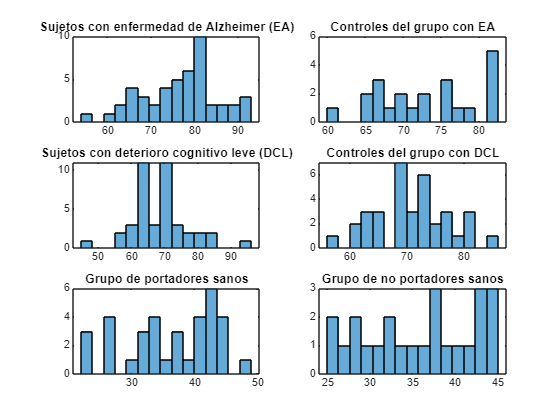

figure(6)
subplot(3,2,1) 
histogram(ad_adni(:,6),15)
title('Sujetos con enfermedad de Alzheimer (EA)')
subplot(3,2,2)
histogram(cnad_adni(:,6),15)
title('Controles del grupo con EA')
subplot(3,2,3)
histogram(dcl(:,6),15)
title('Sujetos con deterioro cognitivo leve (DCL)')
subplot(3,2,4)
histogram(cndcl(:,6),15)
title('Controles del grupo con DCL')
subplot(3,2,5)
histogram(portadores(:,6),15)
title('Grupo de portadores sanos')
subplot(3,2,6)
histogram(no_portadores(:,6),15)
title('Grupo de no portadores sanos')

### Prueba de hipótesis para la diferencia de medias de la anisotropía fraccional para los portadores y los no portadores.

n_p = length(portadores(:,2));
n_np = length(no_portadores(:,2));
var_p = var(portadores(:,2));
var_np = var(no_portadores(:,2));

v = ((var_np/n_np)+(var_p/n_p))^2/((var_np/n_np)^2/(n_np - 1) + (var_p/n_p)^2/(n_p - 1));
t_val = tinv(0.95,v);
t_test = mu_dif_af(9,1)/sqrt(var_np/n_np + var_p/n_p);
if (t_test < t_val)
    disp("Existe evidencia estadísticamente suficiente para determinar") 
    disp("que la anisotropía fraccional de los portadores es significativamente") 
    disp("menor que la de los no portadores")
else
     disp("No existe evidencia estadísticamente suficiente para determinar") 
    disp("que la anisotropía fraccional de los portadores es significativamente") 
    disp("menor que la de los no portadores")
end

Existe evidencia estadísticamente suficiente para determinar


que la anisotropía fraccional de los portadores es significativamente


menor que la de los no portadores


### Prueba de hipótesis para la diferencia de medias de la difusividad media para los portadores y los no portadores.

var_p = var(portadores(:,1));
var_np = var(no_portadores(:,1));

v = ((var_np/n_np)+(var_p/n_p))^2/((var_np/n_np)^2/(n_np - 1) + (var_p/n_p)^2/(n_p - 1));
t_val = tinv(0.05,v);

t_test = mu_dif_dm(9,1)/sqrt(var_np/n_np + var_p/n_p);

if (t_test > t_val)
    disp("Existe evidencia estadísticamente suficiente para determinar") 
    disp("que la difusividad media de los portadores es significativamente") 
    disp("mayor que la de los no portadores")
else
    disp("No existe evidencia estadísticamente suficiente para determinar") 
    disp("que la difusividad media de los portadores es significativamente") 
    disp("mayor que la de los no portadores")
end

Existe evidencia estadísticamente suficiente para determinar


que la difusividad media de los portadores es significativamente


mayor que la de los no portadores


### Prueba de hipótesis para la diferencia de medias de la difusividad media para el grupo de DCL y sus controles.

n_dcl = length(dcl(:,1));
n_cndcl = length(cndcl(:,1));
var_dcl = var(dcl(:,1));
var_cndcl = var(cndcl(:,1));

v = ((var_dcl/n_dcl)+(var_cndcl/n_cndcl))^2/((var_dcl/n_dcl)^2/(n_dcl - 1) + (var_cndcl/n_cndcl)^2/(n_cndcl - 1));
t_val = tinv(0.05,v);

t_test = mu_dif_dm(11,1)/sqrt(var_dcl/n_dcl + var_cndcl/n_cndcl);

if (t_test > t_val)
    disp("Existe evidencia estadísticamente suficiente para determinar") 
    disp("que la difusividad media de los sujetos con deterioro cognitivo") 
    disp("leve (DCL) es significativamente mayor que la de sus controles")
else
    disp("No existe evidencia estadísticamente suficiente para determinar") 
    disp("que la difusividad media de los sujetos con deterioro cognitivo") 
    disp("leve (DCL) es significativamente mayor que la de sus controles")
end

Existe evidencia estadísticamente suficiente para determinar


que la difusividad media de los sujetos con deterioro cognitivo


leve (DCL) es significativamente mayor que la de sus controles


### Prueba de hipótesis para la diferencia de medias de la anisotropía fraccional para el grupo de DCL y sus controles.

var_dcl = var(dcl(:,2));
var_cndcl = var(cndcl(:,2));

v = ((var_dcl/n_dcl)+(var_cndcl/n_cndcl))^2/((var_dcl/n_dcl)^2/(n_dcl - 1) + (var_cndcl/n_cndcl)^2/(n_cndcl - 1));
t_val = tinv(0.95,v);

t_test = mu_dif_af(11,1)/sqrt(var_dcl/n_dcl + var_cndcl/n_cndcl);

if (t_test < t_val)
    disp("Existe evidencia estadísticamente suficiente para determinar") 
    disp("que la anisotropía fraccional de los sujetos con deterioro cognitivo") 
    disp("leve (DCL) es significativamente menor que la de sus controles")
else
    disp("No existe evidencia estadísticamente suficiente para determinar") 
    disp("que la anisotropía fraccional de los sujetos con deterioro cognitivo") 
    disp("leve (DCL) es significativamente menor que la de sus controles")
end

Existe evidencia estadísticamente suficiente para determinar


que la anisotropía fraccional de los sujetos con deterioro cognitivo


leve (DCL) es significativamente menor que la de sus controles


### Prueba de hipótesis para la diferencia de medias de la difusividad media para el grupo de demencia y sus controles.

n_ad_adni = length(ad_adni(:,1));
n_cnad_adni = length(cnad_adni(:,1));
var_ad_adni = var(ad_adni(:,1));
var_cnad_adni = var(cnad_adni(:,1));

v = ((var_ad_adni/n_ad_adni)+(var_cnad_adni/n_cnad_adni))^2/((var_ad_adni/n_ad_adni)^2/(n_ad_adni - 1) + (var_cnad_adni/n_cnad_adni)^2/(n_cnad_adni - 1));
t_val = tinv(0.05,v);

t_test = mu_dif_dm(10,1)/sqrt(var_ad_adni/n_ad_adni + var_cnad_adni/n_cnad_adni);

if (t_test > t_val)
    disp("Existe evidencia estadísticamente suficiente para determinar") 
    disp("que la difusividad media de los sujetos con enfermedad de Alzheimer") 
    disp("es significativamente mayor que la de sus controles")
else
    disp("No  existe evidencia estadísticamente suficiente para determinar") 
    disp("que la difusividad media de los sujetos con enfermedad de Alzheimer") 
    disp("es significativamente mayor que la de sus controles")
end

Existe evidencia estadísticamente suficiente para determinar


que la difusividad media de los sujetos con enfermedad de Alzheimer


es significativamente mayor que la de sus controles


### Prueba de hipótesis para la diferencia de medias de la anisotropía fraccional para el grupo de demencia y sus controles.

var_ad_adni = var(ad_adni(:,2));
var_cnad_adni = var(cnad_adni(:,2));

v = ((var_ad_adni/n_ad_adni)+(var_cnad_adni/n_cnad_adni))^2/((var_ad_adni/n_ad_adni)^2/(n_ad_adni - 1) + (var_cnad_adni/n_cnad_adni)^2/(n_cnad_adni - 1));
t_val = tinv(0.95,v);

t_test = mu_dif_af(10,1)/sqrt(var_ad_adni/n_ad_adni + var_cnad_adni/n_cnad_adni);

if (t_test < t_val)
    disp("Existe evidencia estadísticamente suficiente para determinar") 
    disp("que la anisotropía fraccional de los sujetos con enfermedad de Alzheimer") 
    disp("es significativamente menor que la de sus controles")
else
    disp("No existe evidencia estadísticamente suficiente para determinar") 
    disp("que la anisotropía fraccional de los sujetos con enfermedad de Alzheimer") 
    disp("es significativamente menor que la de sus controles")
end

Existe evidencia estadísticamente suficiente para determinar


que la anisotropía fraccional de los sujetos con enfermedad de Alzheimer


es significativamente menor que la de sus controles


### Análisis de correlación entre las métricas de difusividad y la puntuación del MMSE

#### Grupo de sujetos con enfermedad de Alzheimer

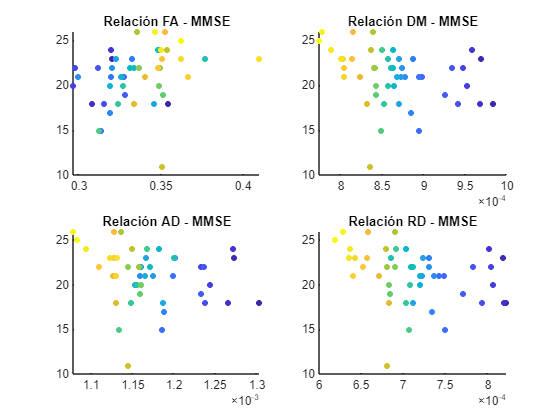

figure(7)
subplot(2,2,1)
scatter(ad_adni(:,2),ad_adni(:,5),20,linspace(1,10,length(ad_adni(:,2))),'filled')
title("Relación FA - MMSE")
subplot(2,2,2)
scatter(ad_adni(:,1),ad_adni(:,5),20,linspace(1,10,length(ad_adni(:,3))),'filled')
title("Relación DM - MMSE")
subplot(2,2,3)
scatter(ad_adni(:,3),ad_adni(:,5),20,linspace(1,10,length(ad_adni(:,4))),'filled')
title("Relación AD - MMSE")
subplot(2,2,4)
scatter(ad_adni(:,4),ad_adni(:,5),20,linspace(1,10,length(ad_adni(:,5))),'filled')
title("Relación RD - MMSE")

r_adni.af = corrcoef(ad_adni(:,2),ad_adni(:,5));
r_adni.dm = corrcoef(ad_adni(:,1),ad_adni(:,5));
r_adni.ad = corrcoef(ad_adni(:,3),ad_adni(:,5));
r_adni.rd = corrcoef(ad_adni(:,4),ad_adni(:,5));

fprintf('Los coeficientes de correlación para la AF, DM, AD y RD con respecto \n al MMSE para el grupo de sujetos con enfermedad de Alzheimer son:\n %1.4f, %1.4f, %1.4f y %1.4f.\n', r_adni.af(1,2), r_adni.dm(1,2), r_adni.ad(1,2), r_adni.rd(1,2))

Los coeficientes de correlación para la AF, DM, AD y RD con respecto 
 al MMSE para el grupo de sujetos con enfermedad de Alzheimer son:
 0.2878, -0.2855, -0.2347 y -0.3029.


#### Grupo de control para grupo de sujetos con enfermedad de Alzheimer

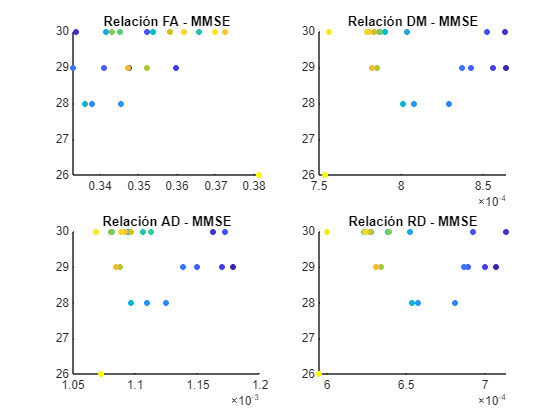

figure(8)
subplot(2,2,1)
scatter(cnad_adni(:,2),cnad_adni(:,5),20,linspace(1,10,length(cnad_adni(:,2))),'filled')
title("Relación FA - MMSE")
subplot(2,2,2)
scatter(cnad_adni(:,1),cnad_adni(:,5),20,linspace(1,10,length(cnad_adni(:,3))),'filled')
title("Relación DM - MMSE")
subplot(2,2,3)
scatter(cnad_adni(:,3),cnad_adni(:,5),20,linspace(1,10,length(cnad_adni(:,4))),'filled')
title("Relación AD - MMSE")
subplot(2,2,4)
scatter(cnad_adni(:,4),cnad_adni(:,5),20,linspace(1,10,length(cnad_adni(:,5))),'filled')
title("Relación RD - MMSE")


r_cnadni.af = corrcoef(cnad_adni(:,2),cnad_adni(:,5));
r_cnadni.dm = corrcoef(cnad_adni(:,1),cnad_adni(:,5));
r_cnadni.ad = corrcoef(cnad_adni(:,3),cnad_adni(:,5));
r_cnadni.rd = corrcoef(cnad_adni(:,4),cnad_adni(:,5));

fprintf('Los coeficientes de correlación para la AF, DM, AD y RD con respecto \n al MMSE para el grupo de control para Alzheimer son:\n %1.4f, %1.4f, %1.4f y %1.4f.\n', r_cnadni.af(1,2), r_cnadni.dm(1,2), r_cnadni.ad(1,2), r_cnadni.rd(1,2))

Los coeficientes de correlación para la AF, DM, AD y RD con respecto 
 al MMSE para el grupo de control para Alzheimer son:
 -0.0267, 0.0323, 0.0526 y 0.0213.


#### Grupo de sujetos con deterioro cognitivo leve

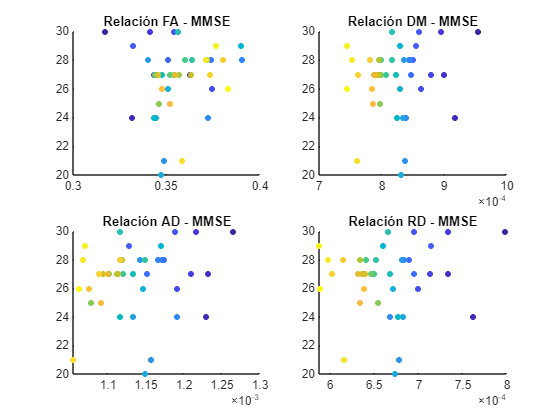

figure(9)
subplot(2,2,1)
scatter(dcl(:,2),dcl(:,5),20,linspace(1,10,length(dcl)),'filled')
title("Relación FA - MMSE")
subplot(2,2,2)
scatter(dcl(:,1),dcl(:,5),20,linspace(1,10,length(dcl)),'filled')
title("Relación DM - MMSE")
subplot(2,2,3)
scatter(dcl(:,3),dcl(:,5),20,linspace(1,10,length(dcl)),'filled')
title("Relación AD - MMSE")
subplot(2,2,4)
scatter(dcl(:,4),dcl(:,5),20,linspace(1,10,length(dcl)),'filled')
title("Relación RD - MMSE")

r_dcl.af = corrcoef(dcl(:,2),dcl(:,5));
r_dcl.dm = corrcoef(dcl(:,1),dcl(:,5));
r_dcl.ad = corrcoef(dcl(:,3),dcl(:,5));
r_dcl.rd = corrcoef(dcl(:,4),dcl(:,5));

fprintf('Los coeficientes de correlación para la AF, DM, AD y RD con respecto \n al MMSE para el grupo de sujetos con deterioro congnitivo leve son:\n %1.4f, %1.4f, %1.4f y %1.4f.\n', r_dcl.af(1,2), r_dcl.dm(1,2), r_dcl.ad(1,2), r_dcl.rd(1,2))

Los coeficientes de correlación para la AF, DM, AD y RD con respecto 
 al MMSE para el grupo de sujetos con deterioro congnitivo leve son:
 0.1229, 0.1344, 0.1732 y 0.1053.


#### Grupo de control para el grupo de deterioro cognitivo leve

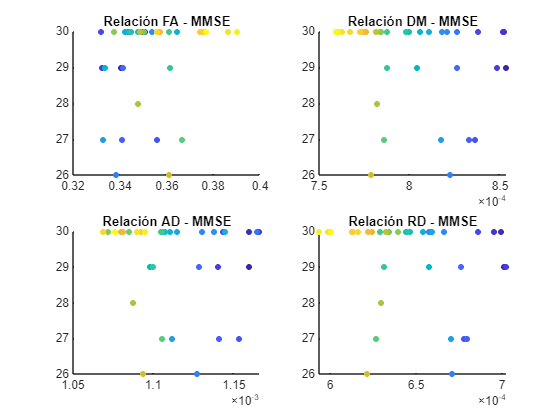

figure(10)
subplot(2,2,1)
scatter(cndcl(:,2),cndcl(:,5),20,linspace(1,10,length(cndcl)),'filled')
title("Relación FA - MMSE")
subplot(2,2,2)
scatter(cndcl(:,1),cndcl(:,5),20,linspace(1,10,length(cndcl)),'filled')
title("Relación DM - MMSE")
subplot(2,2,3)
scatter(cndcl(:,3),cndcl(:,5),20,linspace(1,10,length(cndcl)),'filled')
title("Relación AD - MMSE")
subplot(2,2,4)
scatter(cndcl(:,4),cndcl(:,5),20,linspace(1,10,length(cndcl)),'filled')
title("Relación RD - MMSE")


r_cndcl.af = corrcoef(cndcl(:,2),cndcl(:,5));
r_cndcl.dm = corrcoef(cndcl(:,1),cndcl(:,5));
r_cndcl.ad = corrcoef(cndcl(:,3),cndcl(:,5));
r_cndcl.rd = corrcoef(cndcl(:,4),cndcl(:,5));

fprintf('Los coeficientes de correlación para la AF, DM, AD y RD con respecto \n al MMSE para el grupo de control para deterioro congnitivo leve son:\n %1.4f, %1.4f, %1.4f y %1.4f.\n', r_cndcl.af(1,2), r_cndcl.dm(1,2), r_cndcl.ad(1,2), r_cndcl.rd(1,2))

Los coeficientes de correlación para la AF, DM, AD y RD con respecto 
 al MMSE para el grupo de control para deterioro congnitivo leve son:
 0.2260, -0.1885, -0.1351 y -0.2028.


#### Grupo de sujetos sanos portadores del gen

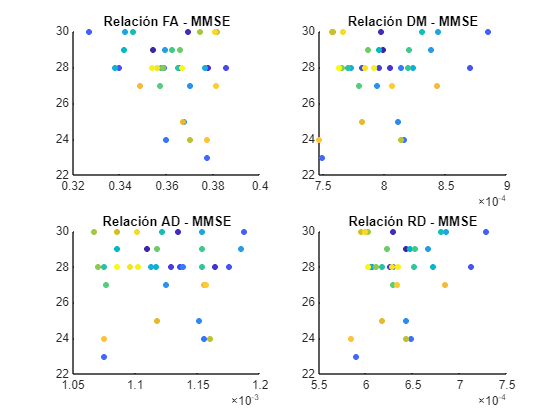

figure(11)
subplot(2,2,1)
scatter(portadores(:,2),portadores(:,5),20,linspace(1,10,length(portadores)),'filled')
title("Relación FA - MMSE")
subplot(2,2,2)
scatter(portadores(:,1),portadores(:,5),20,linspace(1,10,length(portadores)),'filled')
title("Relación DM - MMSE")
subplot(2,2,3)
scatter(portadores(:,3),portadores(:,5),20,linspace(1,10,length(portadores)),'filled')
title("Relación AD - MMSE")
subplot(2,2,4)
scatter(portadores(:,4),portadores(:,5),20,linspace(1,10,length(portadores)),'filled')
title("Relación RD - MMSE")


r_portadores.af = corrcoef(portadores(:,2),portadores(:,5));
r_portadores.dm = corrcoef(portadores(:,1),portadores(:,5));
r_portadores.ad = corrcoef(portadores(:,3),portadores(:,5));
r_portadores.rd = corrcoef(portadores(:,4),portadores(:,5));

fprintf('Los coeficientes de correlación para la AF, DM, AD y RD con respecto \n al MMSE para el grupo de portadores sanos son:\n %1.4f, %1.4f, %1.4f y %1.4f.\n', r_portadores.af(1,2), r_portadores.dm(1,2), r_portadores.ad(1,2), r_portadores.rd(1,2))

Los coeficientes de correlación para la AF, DM, AD y RD con respecto 
 al MMSE para el grupo de portadores sanos son:
 -0.2743, 0.2128, 0.0320 y 0.2570.


#### Grupo de sujetos sanos no portadores

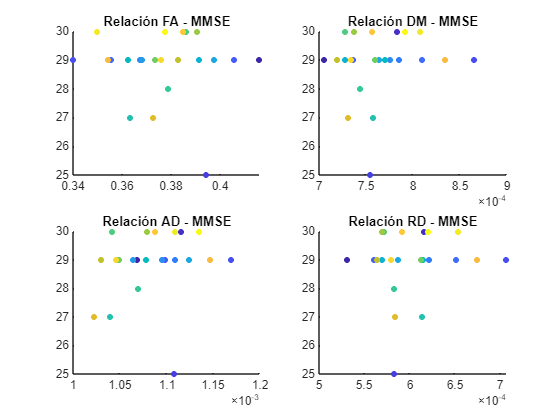

figure(12)
subplot(2,2,1)
scatter(no_portadores(:,2),no_portadores(:,5),20,linspace(1,10,length(no_portadores)),'filled')
title("Relación FA - MMSE")
subplot(2,2,2)
scatter(no_portadores(:,1),no_portadores(:,5),20,linspace(1,10,length(no_portadores)),'filled')
title("Relación DM - MMSE")
subplot(2,2,3)
scatter(no_portadores(:,3),no_portadores(:,5),20,linspace(1,10,length(no_portadores)),'filled')
title("Relación AD - MMSE")
subplot(2,2,4)
scatter(no_portadores(:,4),no_portadores(:,5),20,linspace(1,10,length(no_portadores)),'filled')
title("Relación RD - MMSE")

r_no_portadores.af = corrcoef(no_portadores(:,2),no_portadores(:,5));
r_no_portadores.dm = corrcoef(no_portadores(:,1),no_portadores(:,5));
r_no_portadores.ad = corrcoef(no_portadores(:,3),no_portadores(:,5));
r_no_portadores.rd = corrcoef(no_portadores(:,4),no_portadores(:,5));

fprintf('Los coeficientes de correlación para la AF, DM, AD y RD con respecto \n al MMSE para el grupo de portadores sanos son:\n %1.4f, %1.4f, %1.4f y %1.4f.\n', r_no_portadores.af(1,2), r_no_portadores.dm(1,2), r_no_portadores.ad(1,2), r_no_portadores.rd(1,2))

Los coeficientes de correlación para la AF, DM, AD y RD con respecto 
 al MMSE para el grupo de portadores sanos son:
 -0.0674, 0.1566, 0.1940 y 0.1185.


### Análisis de correlación entre las métricas de difusividad y la edad para los grupos portadores y no portadores

#### Grupo de sujetos portadores

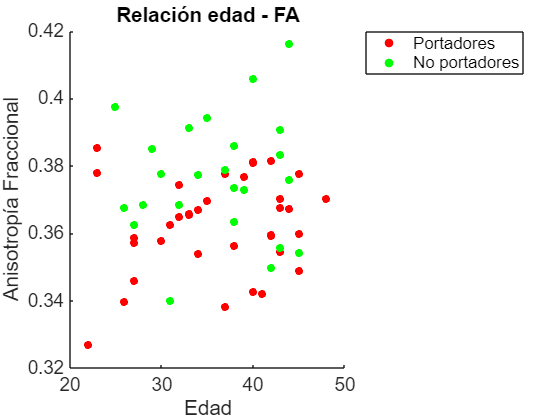

figure(13)
scatter(portadores(:,6),portadores(:,2),30,'MarkerEdgeColor','r','MarkerFaceColor','r')
hold on
scatter(no_portadores(:,6),no_portadores(:,2),30,'MarkerEdgeColor','g','MarkerFaceColor','g')
legend('Portadores','No portadores','Location','northeastoutside')
title("Relación edad - FA")
xlabel('Edad')
ylabel('Anisotropía Fraccional')
set(gca,'FontSize',14)

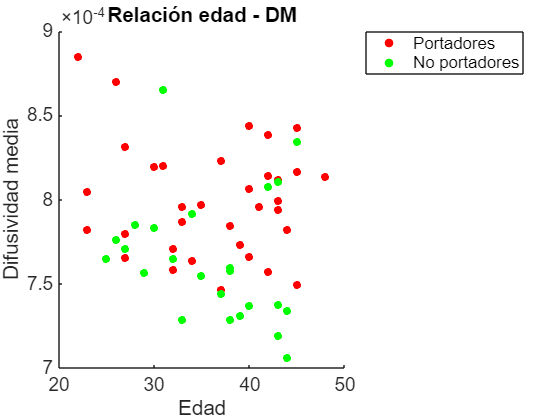

figure(14)
scatter(portadores(:,6),portadores(:,1),30,'MarkerEdgeColor','r','MarkerFaceColor','r')
hold on
scatter(no_portadores(:,6),no_portadores(:,1),30,'MarkerEdgeColor','g','MarkerFaceColor','g')
legend('Portadores','No portadores','Location','northeastoutside')
title("Relación edad - DM")
xlabel('Edad')
ylabel('Difusividad media')
set(gca,'FontSize',14)

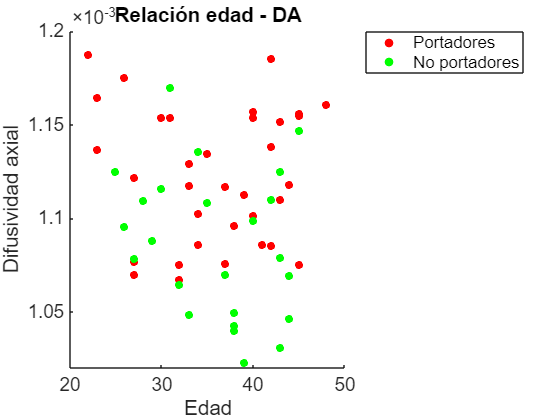

figure(15)
scatter(portadores(:,6),portadores(:,3),30,'MarkerEdgeColor','r','MarkerFaceColor','r')
hold on
scatter(no_portadores(:,6),no_portadores(:,3),30,'MarkerEdgeColor','g','MarkerFaceColor','g')
legend('Portadores','No portadores','Location','northeastoutside')
title("Relación edad - DA")
xlabel('Edad')
ylabel('Difusividad axial')
set(gca,'FontSize',14)

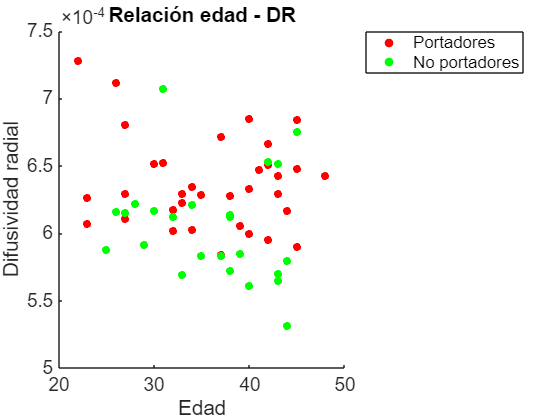

figure(16)
scatter(portadores(:,6),portadores(:,4),30,'MarkerEdgeColor','r','MarkerFaceColor','r')
hold on
scatter(no_portadores(:,6),no_portadores(:,4),30,'MarkerEdgeColor','g','MarkerFaceColor','g')
legend('Portadores','No portadores','Location','northeastoutside')
title("Relación edad - DR")
xlabel('Edad')
ylabel('Difusividad radial')
set(gca,'FontSize',14)